# **2. COLLECTING AND ANALYSING DATA FROM EXPERIMENTS**

## **PART 2.2**

% start fresh
clc, clearvars, close all

% import data set

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 17);

% Specify sheet and range
opts.Sheet = "Public goods contributions";
opts.DataRange = "A3:Q26";

% Specify column names and types
opts.VariableNames = ["Period", "Copenhagen", "Dnipropetrovs_k", "Minsk", "St_Gallen", "Muscat", "Samara", "Zurich", "Boston", "Bonn", "Chengdu", "Seoul", "Riyadh", "Nottingham", "Athens", "Istanbul", "Melbourne"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
tempdata = readtable("C:\Users\HP\Doing Economics\MATLAB\Project 2\doing-economics-datafile-working-in-excel-project-2.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
tempdata

tempdata = 24×17 table
    Period    Copenhagen    Dnipropetrovs_k    Minsk     St_Gallen    Muscat    Samara    Zurich    Boston     Bonn     Chengdu    Seoul     Riyadh    Nottingham    Athens    Istanbul    Melbourne
    ______    __________    _______________    ______    _________    ______    ______    ______    ______    ______    _______    ______    ______    __________    ______    ________    _________

    

% remove empty rows between the two sets of data
tempdata = tempdata(~any(ismissing(tempdata), 2), :)

tempdata = 20×17 table
    Period    Copenhagen    Dnipropetrovs_k    Minsk     St_Gallen    Muscat    Samara    Zurich    Boston     Bonn     Chengdu    Seoul     Riyadh    Nottingham    Athens    Istanbul    Melbourne
    ______    __________    _______________    ______    _________    ______    ______    ______    ______    ______    _______    ______    ______    __________    ______    ________    _________

    

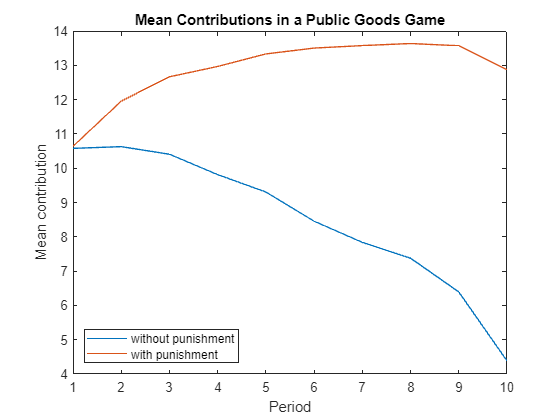

% add period means to the table
tempdata.Mean = mean(tempdata(:, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]), 2).Variables;

% plot mean contributions with and without punishment using line charts
plot(tempdata(1:10, :), 'Period', 'Mean');
hold on;
plot(tempdata(11:20, :), 'Period', 'Mean');
title('Mean Contributions in a Public Goods Game');
xlabel('Period');
ylabel('Mean contribution');
hold off;
legend('without punishment', 'with punishment', 'Location', 'southwest');

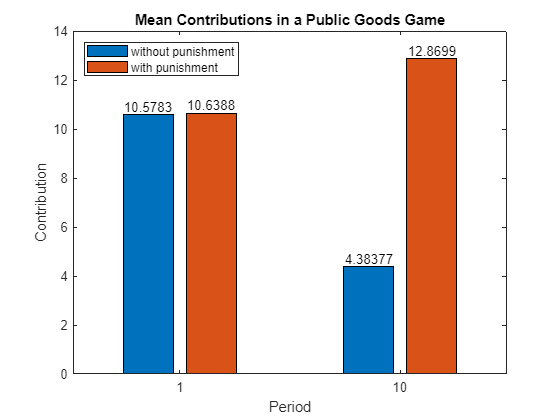

% plot mean contributions with and without punishment using column charts
b = bar([tempdata(1, 'Mean').Variables tempdata(11, 'Mean').Variables; tempdata(10, 'Mean').Variables tempdata(20, 'Mean').Variables]);
title('Mean Contributions in a Public Goods Game');
xlabel('Period');
xticklabels({'1', '10'});
ylabel('Contribution');
text(b(1).XEndPoints, b(1).YEndPoints, string(b(1).YData), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
text(b(2).XEndPoints, b(2).YEndPoints, string(b(2).YData), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
legend('without punishment', 'with punishment', 'Location', 'northwest');

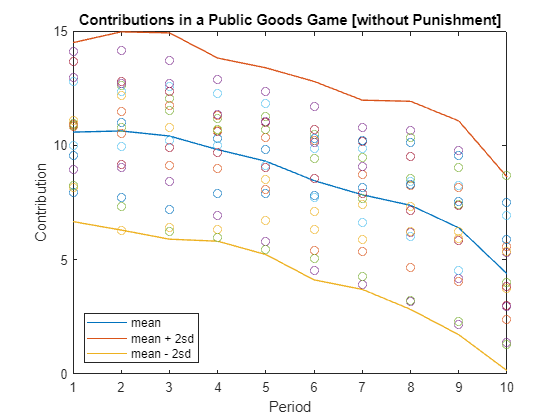

% add period standard deviations to the table
tempdata.SD = std(tempdata(:, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]), 1, 2).Variables;

% calculate two standard deviation interval
plus2 = tempdata.Mean + (2 * tempdata.SD);
minus2 = tempdata.Mean - (2 * tempdata.SD);

% plot mean line for without punishment
plot(tempdata(1:10, :), 'Period', 'Mean');
hold on;

% plot two standard deviation interval for without punishment
plot(tempdata(1:10, :).Period, plus2(1:10));
plot(tempdata(1:10, :).Period, minus2(1:10));

% plot actual data for without punishment
for i = [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]
    scatter(tempdata(1:10, :), 'Period', i);
end

title('Contributions in a Public Goods Game [without Punishment]');
xlabel('Period');
ylabel('Contribution');
hold off;
legend('mean', 'mean + 2sd', 'mean - 2sd', 'Location', 'southwest');

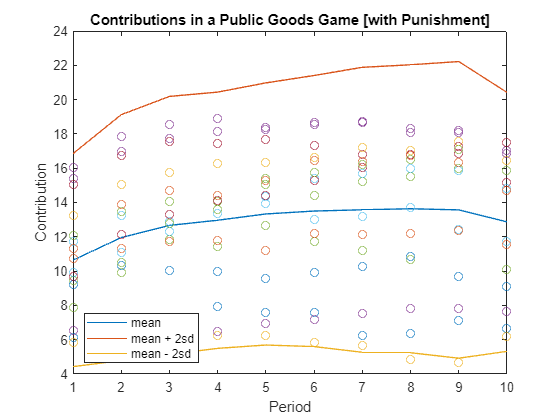

% plot mean line for with punishment
plot(tempdata(11:20, :), 'Period', 'Mean');
hold on;

% plot two standard deviation interval for with punishment
plot(tempdata(11:20, :).Period, plus2(11:20));
plot(tempdata(11:20, :).Period, minus2(11:20));

% plot actual data for with punishment
for i = [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]
    scatter(tempdata(11:20, :), 'Period', i);
end

title('Contributions in a Public Goods Game [with Punishment]');
xlabel('Period');
ylabel('Contribution');
hold off;
legend('mean', 'mean + 2sd', 'mean - 2sd', 'Location', 'southwest');

% add the period maximum and minimum to the table
tempdata.Max = max(tempdata(:, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]), [], 2).Variables;
tempdata.Min = min(tempdata(:, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]), [], 2).Variables;

% print summary statistics for without punishment
t1 = table(tempdata([1 10], :).Period, tempdata([1 10], :).Mean, tempdata([1 10], :).SD, tempdata([1 10], :).Max, tempdata([1 10], :).Min, 'VariableNames', {'Period', 'Mean', 'SD', 'Max', 'Min'});
disp(t1);

    Period     Mean       SD       Max       Min  
    ______    ______    ______    ______    ______

       1      10.578    1.9566    14.103    7.9583
      10      4.3838    2.1177    8.6818       1.3



% print summary statistics for with punishment
t2 = table(tempdata([11 20], :).Period, tempdata([11 20], :).Mean, tempdata([11 20], :).SD, tempdata([11 20], :).Max, tempdata([11 20], :).Min, 'VariableNames', {'Period', 'Mean', 'SD', 'Max', 'Min'});
disp(t2);

    Period     Mean       SD       Max       Min  
    ______    ______    ______    ______    ______

       1      10.639    3.1054    16.018    5.8182
      10       12.87    3.7742    17.512    6.2045



## **PART 2.3**

% calculate p-values for periods 1 and 10
[h1, p1] = ttest(tempdata(1, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]).Variables, tempdata(11, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]).Variables);
[h2, p2] = ttest(tempdata(10, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]).Variables, tempdata(20, [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17]).Variables);
fprintf('p-value for period 1: %f\np-value for period 10: %f', p1, p2);

p-value for period 1: 0.882795
p-value for period 10: 0.000010